%% online decoder1: Base KF
% take in SBP
% SpikingBandPower: The spiking band power for all 96 channels accumulated each ms, acquired via the following procedure:
% 			1) Filtered to 300-1,000Hz using the Digital Filter Editor in the Central Software Suite (Blackrock Microsystems, LLC).
% 			2) Sampled at 2 kilo-samples per second.
% 			3) Transmitted from the Cerebus system to the xPC Target system (see methods in the main paper) at 2 kilo-samples per second.
% 			4) All samples received by the xPC within 1ms are absolute-valued then summed within each channel, contained in the SpikingBandPower field.
addpath 'D:\documents\Rouse Lab\BCI project\BCI_prelim'
% testing neural signal
T = 5; %s
dt = 0.01;  %Time step, 10 ms
freq = 2;  %#frequency of movement
N = 384;  %# neurons 10
time_array = 0:dt:T;
mu = T/2;
sigma = 1.5;

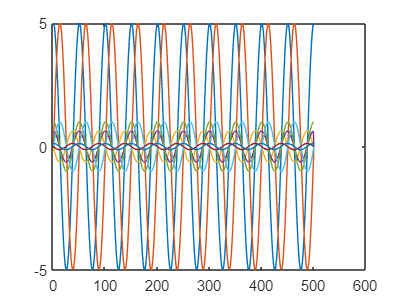

%X - movement in 2 dims, rows 1 and 2
%Use sinusoids as movement
X = 5*cos(2*pi*freq*(0:dt:T));
X(2,:) = 5*sin(2*pi*freq*(0:dt:T));%change amplitude for classidfying moveemnt types
XS = 5*0.2*cos(2*pi*freq*(0:dt:T));
XS(2,:) = 5*0.2*sin(2*pi*freq*(0:dt:T));
% %Use gaussian distribution as 1D movement
% X=normpdf((0:dt:T),mu,sigma);
% %figure;plot((0:dt:T),y);hold on; plot((0:dt:T),4.*y)
% %Use band limited noise as movement
% [b,a] = butter(2, 5/(0.5/dt), 'low');
% X = randn(2, length(time_array));
% X = filtfilt(b,a,X')';
% X = X + 0.001*randn(size(X));
% X = awgn(X,10,'measured');
% XS = XS + 0.001*randn(size(XS));
% XS = awgn(XS,10,'measured');
%rows 3 and 4, velocity of movement in 2 dims
X = [X;[diff(X,1,2),[0;0]]];
X = [X; ones(1,size(X,2));+ones(1,size(XS,2))];
XS = [XS;[diff(XS,1,2),[0;0]]];
XS = [XS; ones(1,size(XS,2));-ones(1,size(XS,2))];

% X = [X;[diff(X,2),[0,0]]];
%Y - tuned firing rates of N neurons
pos_tuning = 2*pi*rand(N,1);
vel_tuning = 2*pi*rand(N,1);
spd_tuning = -1 + 2*rand(N,1);%uniformly distributed state tuning from [-2pi,2pi]
tuning = [cos(pos_tuning), sin(pos_tuning), cos(vel_tuning), sin(vel_tuning), spd_tuning];
% tuning = [pos_tuning vel_tuning];
Y = tuning(:,1)*X(1,:) + tuning(:,2)*X(2,:) + tuning(:,3)*X(3,:) + tuning(:,4)*X(4,:) + tuning(:,5)*X(6,:);
% Y = tuning(:,1)*X(1,:) + tuning(:,2)*X(2,:); 
Y = Y + 2*randn(size(Y));

figure
plot(X(1:4,:)')
hold on
plot(XS(1:4,:)')

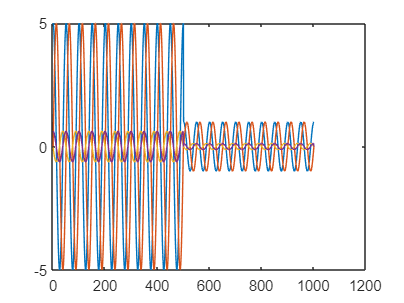


%small tuning
pos_tuning2 = 10*2*pi*rand(N,1);
vel_tuning2 = 10*2*pi*rand(N,1);
%add spped tuning(+/-) & diff amp
spd_tuning2 = -1 + 2*rand(N,1);%uniformly distributed state tuning from [-2pi,2pi]
tuning2 = [cos(pos_tuning2), sin(pos_tuning2), cos(vel_tuning2), sin(vel_tuning2), spd_tuning2];
YS = tuning2(:,1)*XS(1,:) + tuning2(:,2)*XS(2,:) + tuning2(:,3)*XS(3,:) + tuning2(:,4)*XS(4,:) + tuning2(:,5)*XS(6,:);
YS = YS + 2*randn(size(YS));

%combine X/XS in timepoint
%set movement switch onset at tp 300
XX = [X,XS];
YY = [Y,YS];
figure
plot(XX(1:4,:)')

%identify timepoint when the switch happens
%train LDA for movement discriminator/when new data get fed in use MdlLinear.Coeffs to predict movement type
MdlLinear = fitcdiscr(YY',XX(6,:),'DiscrimType','linear'); 
%next/undertand how to use MdlLinear.coeff matrix to predict and potential limitation


%detect y switch (e.g. 111-1111-1-1-11-1-1)--HMM
sw=find(MdlLinear.Y==1);
sw=sw(end);
% trainer
% switch trainer
%     case 1
        [A,C,Q,W,P_0] = train_online_kalman(XX(1:5,1:sw),YY(:,1:sw),dt);

        predX = zeros(size(A,1), size(YY(:,1:sw),2));
        X_0(1:5,1) = XX(1:5,1);
        P=P_0;
        predX(:,1) = X_0;
        K = zeros(size(W,1), size(Q,1), size(YY(:,1:sw),2));
        for t = 2:size(YY(:,1:sw),2)   
            %Calculate Kalman gain K
            prior_P = A*P*A' + W;
            S = C*prior_P*C' + Q;%state
            K(:,:,t) = prior_P*C'*inv(S);%gain
             %Update movement covariance matrix
            P = (eye(size(A,1)) - K(:,:,t)*C)*prior_P;
        end
        tic
        for t = 2:size(YY(:,1:sw),2) 
            %Use current firing rates to estimate next movement
            YY_error = YY(:,t) - C*predX(:,t-1);
            predX(:,t) = predX(:,t-1) + K(:,:,t)*YY_error;
        end
        toc

Elapsed time is 0.016873 seconds.


%     case -1
        [AS,CS,QS,WS,PS_0] = train_online_kalman(XX(1:5,sw+1:end),YY(:,sw+1:end),dt);

        predXS = zeros(size(AS,1), size(YY(:,sw+1:end),2));
        XS_0(1:5,1) = XX(1:5,sw+1);
        PS=PS_0;
        predXS(:,1) = XS_0;
        KS = zeros(size(WS,1), size(QS,1), size(YY(:,sw+1:end),2));
        for t = 2:size(YY(:,sw+1:end),2)   
            %Calculate Kalman gain K
            prior_PS = AS*PS*AS' + WS;
            SS = CS*prior_PS*CS' + QS;%state
            KS(:,:,t) = prior_PS*CS'*inv(SS);%gain
             %Update movement covariance matrix
            PS = (eye(size(AS,1)) - KS(:,:,t)*CS)*prior_PS;
        end
        tic
        for t = 2:size(YY(:,sw+1:end),2) 
            %Use current firing rates to estimate next movement
            Y_errorS = YY(:,sw+t) - CS*predXS(:,t-1);
            predXS(:,t) = predXS(:,t-1) + KS(:,:,t)*Y_errorS;
        end
        toc      

Elapsed time is 0.015665 seconds.


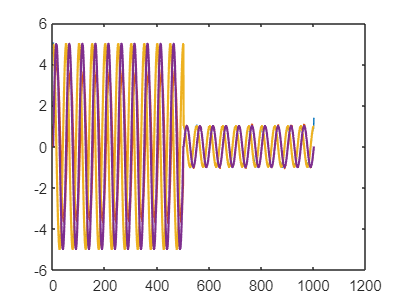

% end

figure;
plot([predX(1:2,:),predXS(1:2,:)]')
hold on
plot(XX(1:2,:)','LineWidth',1.5)


%patch note/04/18: 
% 1. discriminator only catches the last point of label
%1 always assuming small movement later, but won't work if predicted 1 in
%small movements as outliers
% 2. kalman-filter sensitive to input magnitude, if going lower then 1 here
% (XS=0.2X) prediction drift, but if set X_0 farther away would work?(below
% e.g.)

## test for separate trainers

%Inputs:        Y:			Neural data of size [t, N], where t is the
%							number of binned samples and neu is the number
%							of SBP channels.
%				X:			Behavioral data of size [t, b], where t is the
%							number of binned samples and b is the
%							dimensionality of behavior. This code assumes
%							the order [position, velocity], where for
%							multidimensional filters, all positions should
%							appear prior to all velocities.
%				dt:	(optional) The size of the accumulation period,
%							in ms. This defaults to 32.
%
% initialize-from create kalman
% set initial states
% W
% A
% C
% Q
[A,C,Q,W,P_0] = train_online_kalman(X(1:5,:),Y,dt);

predX = zeros(size(A,1), size(Y,2));
X_0(1:5,1) = X(1:5,1);
predX(:,1) = X_0;
%Pj=P_0;
%VELOCITY OUTPUT
%store previous state Xt, the position and velocity
%at time t is used to calculate the position at time t+1
%state_dim--if task set to different states(e.g. finger movements)/potentially edit
% ch=N; %ch--channels chosen to decode
% Xtprev = Xt;
% Xtoutprev = Xtout;
% Normal Update
% Ct = C(1:length(ch),:);
% Wt = W;
% At = A;
P = P_0;
% % Predict:
% Xt = At*Xt;                 % prediction from previous state
% prior_P = At*Pj*At'+Wt;
% 
% % Innovate/Update:
% Kt = Pj*C'/(C*Pj*C' + Q);
% %Kt = (eye(size(prior_P))+prior_P*CtQinvCT)\prior_P*CtQinvT;
% Y_error = Y(:,t) - C*predX(:,t-1);
% Xt = Xt + Kt*Y_error;      % correct prediction   (double(lags(chans,binLag+1)) - Ct*Xt)
% Pj = (eye(size(A1,1)) - Kt*Ct)*prior_P;                        % Update movement covariance matrix


[A,C,Q,W,P_0] = train_online_kalman(XX(1:5,:),YY,dt);

predXX = zeros(size(A,1), size(YY,2));
X_0(1:5,1) = XX(1:5,1);
P=P_0;
predXX(:,1) = X_0;
K = zeros(size(W,1), size(Q,1), size(YY,2));
for t = 2:size(YY,2)   
    %Calculate Kalman gain K
    prior_P = A*P*A' + W;
    S = C*prior_P*C' + Q;%state
    K(:,:,t) = prior_P*C'*inv(S);%gain
     %Update movement covariance matrix
    P = (eye(size(A,1)) - K(:,:,t)*C)*prior_P;
end
tic
for t = 2:size(YY,2) 
    %Use current firing rates to estimate next movement
    Y_error = YY(:,t) - C*predXX(:,t-1);
    predXX(:,t) = predXX(:,t-1) + K(:,:,t)*Y_error;
    
   
end

toc

Elapsed time is 0.021476 seconds.


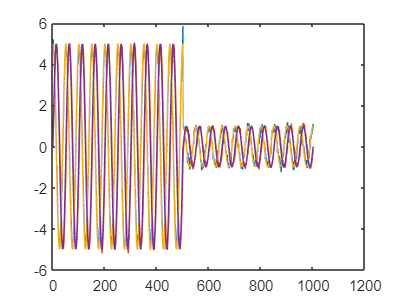


figure
plot(predXX(1:2,:)')
hold on
plot(XX(1:2,:)')

%%
% tic
% for t = 2:size(Y,2)   
%     %Calculate Kalman gain K
%     prior_P = A*P*A' + W;
%     S = C*prior_P*C' + Q;%state
%     K = prior_P*C'*inv(S);%gain
%     
%     %Use current firing rates to estimate next movement
%     Y_error = Y(:,t) - C*predX(:,t-1);
%     predX(:,t) = predX(:,t-1) + K*Y_error;
%     
%     %Update movement covariance matrix
%     P = (eye(size(A,1)) - K*C)*prior_P;
% end
% 
% toc
% i=1;

K = zeros(size(W,1), size(Q,1), size(Y,2));
for t = 2:size(Y,2)   
    %Calculate Kalman gain K
    prior_P = A*P*A' + W;
    S = C*prior_P*C' + Q;%state
    K(:,:,t) = prior_P*C'*inv(S);%gain
     %Update movement covariance matrix
    P = (eye(size(A,1)) - K(:,:,t)*C)*prior_P;
end
tic
for t = 2:size(Y,2) 
    %Use current firing rates to estimate next movement
    Y_error = Y(:,t) - C*predX(:,t-1);
    predX(:,t) = predX(:,t-1) + K(:,:,t)*Y_error;
    
   
end

toc

Elapsed time is 0.018123 seconds.


## output predict position

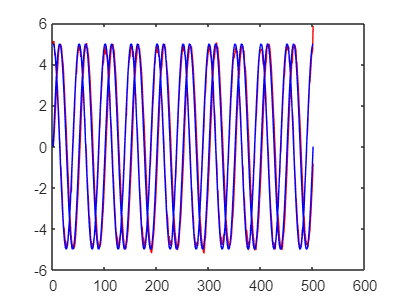

figure
plot(predX(1:2,:)','r')
hold on
plot(X(1:2,:)','b')

## Multistate KF

*for input=1:N*

*    if SBP fall in Low categery*

*        use KF(1) get coef_H    *

*    elseif SBP fall in Mid categery*

*        use KF(2) get coef_M*

*    elseif SBP fall in Hi categery*

*        use KF(3) get coef_L*

*    end*

*end*

% XS = 0.2*cos(0.5*pi+2*pi*freq*(0:dt:T))+1.5;
% XS(2,:) = 0.2*sin(0.5*pi+2*pi*freq*(0:dt:T))+0.5;
XS = 0.2*cos(2*pi*freq*(0:dt:T));
XS(2,:) = 0.2*sin(2*pi*freq*(0:dt:T));
XS = [XS;[diff(XS,1,2),[0;0]]];
XS = [XS; ones(1,size(XS,2));-ones(1,size(XS,2))];
pos_tuning2 = 10*2*pi*rand(N,1);%
vel_tuning2 = 10*2*pi*rand(N,1);%
%add spped tuning(+/-) & diff amp
spd_tuning2 = -1 + 2*rand(N,1);%uniformly distributed state tuning from [-2pi,2pi]
tuning2 = [cos(pos_tuning2), sin(pos_tuning2), cos(vel_tuning2), sin(vel_tuning2), spd_tuning2];
YS = tuning2(:,1)*XS(1,:) + tuning2(:,2)*XS(2,:) + tuning2(:,3)*XS(3,:) + tuning2(:,4)*XS(4,:) + tuning2(:,5)*XS(6,:);
YS = YS + 2*randn(size(YS));

predXX = KLpredict(XS,YS,dt);

Elapsed time is 0.007993 seconds.


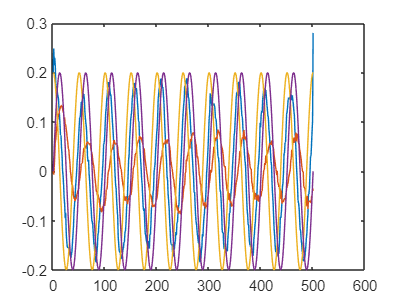

figure
plot(predXX(1:2,:)')
hold on
plot(XS(1:2,:)')

## Next: try COT task data/optimize decoder(nonlinear/ReFit)

% dates = {'0717' '0714' '0720' '0712' '0713' '0731' '0802' '0630' '0703' '0801' '0705' '0706'};%'0630' '0703' '0705' '0713' '0712' '0731'
% [output_data, PeakInfo, data_info, initPeak_flag_cat, X_F, X_F_cat, date_label] = DataReading(dates);
testdata = load('D:\documents\2020 summer-LFAD\COT_task\DataFiles\monk_p\P_Spikes_20170630-data.mat');
InstructIndex = find(strcmpi('Instruct', testdata.TrialSettings.align_names)); 
EndIndex = find(strcmpi('End', testdata.TrialSettings.align_names));

instruct_offset = 10;  %100 ms (10 samples) after instruction appears
end_offset = 25; %250 ms (25 samples), final hold is 500-600

dataMask_init = false(size(testdata.CursorSpeedRaw));
dataMask_cor = false(size(testdata.CursorSpeedRaw));
for tr = 1:size(dataMask_init,1)
    if isnan(testdata.TrialInfo.initCor_boundary_sample(tr))
        dataMask_init(tr,:) = false;
        dataMask_cor (tr,:) = false;
    else
        dataMask_init(tr,(testdata.TrialInfo.align_samples(tr,InstructIndex)-instruct_offset):(testdata.TrialInfo.initCor_boundary_sample(tr)-1)) = true;
        if any(~testdata.PeakInfo.initPeak_flag & tr==testdata.PeakInfo.trial_ids_peakVel)
            dataMask_cor(tr,testdata.TrialInfo.initCor_boundary_sample(tr):testdata.TrialInfo.align_samples(tr,EndIndex)-end_offset) = true;
        end
    end
end


X_init_pos = getMaskedData(testdata.JoystickPos_disp,dataMask_init);
X_init_pos = squeeze(X_init_pos(1,:,:));
X_init_vel = getMaskedData(testdata.CursorSpeedRaw,dataMask_init);
X_init_vel = squeeze(X_init_vel(1,:,:));
X_corr_pos = getMaskedData(testdata.JoystickPos_disp,dataMask_cor);
X_corr_pos =squeeze(X_corr_pos(1,:,:));
X_corr_vel = getMaskedData(testdata.CursorSpeedRaw,dataMask_cor);
X_corr_vel = squeeze(X_corr_vel(1,:,:));

X_init_vel = [[0,0];diff(X_init_pos,2,1);[0,0]];
X_init = [X_init_pos';X_init_vel;ones(1,size(X_init_pos,1))];

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

X_corr = [X_corr_pos';X_corr_vel;ones(1,size(X_corr_pos,1))];
X = cat(2,X_init,X_corr);
Y_init = getMaskedData(testdata.SpikeFiringRates,dataMask_init);
Y_init = squeeze(Y_init(1,:,:));
Y_corr = getMaskedData(testdata.SpikeFiringRates,dataMask_cor);
Y_corr = squeeze(Y_corr(1,:,:));
Y = cat(2,Y_init',Y_corr');
% nanidx=isnan(X(1,:));
% nanidx=find(nanidx==1,1);
% X=squeeze(testdata.JoystickPos_disp(1,:,:));%[d T]
% X = X';
% X = [X;[diff(X,1,2),[0;0]]];
% X = [X; ones(1,size(X,2));+ones(1,size(X,2))];
% X = X(:,1:nanidx);
% Y=squeeze(testdata.SpikeFiringRates(1,:,:));%[N T]
% Y = Y';
% Y = Y(:,1:nanidx);
predX = KLpredict(X_corr,Y_corr',dt);
figure
plot(predX(1:2,:)')
hold on
plot(X(1:2,:)')